# Plot Biquadratic Lagrange Polynomials in Physical Space

Generates three graphs concerning a two-dimensional biquadratic mesh in a tiled format: The two-dimensional basis functions, the provided parametric location mapped onto the physical space and the distribution of the geometric Jacobian in the parametric space of the provided element.

function t = plot2dBiquadraticLagrangePolynomialsOnPhysicalSpace ...
    (el, msh, numVertices, l1L2, l2L2, l3L2, ij)

## **Function description**

Displays the bilinear basis functions on the two-dimensional biquadratic quadrilateral mesh in the physical space.

**                            Input :**

                                 `el` : The element for which the parametric location is sought to be displayed in the physical space

                               `msh` : The one-dimensional biquadratic mesh using four-noded elements as a structure with the following fields:

                                          .`nodes` : Number of nodes in the one-dimensional mesh

                                    .`elements` : Number of elements in the one-dimensional mesh

               `numVertices` : Number of vertices in the bilinear quadratic mesh

   `l1_L2`, `l2_L2`, `l3_L2` : The three Lagrange polynomials for the one-dimensional quadratic element

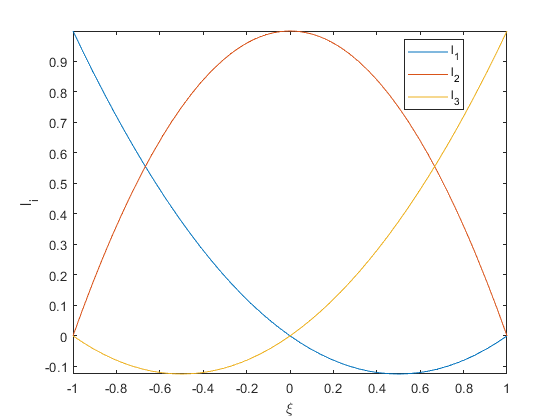

                                 `ij` : Legend entries for the plot, which should be an array with nine elements

**                         Output :**

                                   `t` : Handle to the tiledlayout graphical object

## **Function implementation**

### **Input validation**

    arguments
        el (1, 1) double {mustBeInteger, mustBeGreaterThanOrEqual(el, 1)}
        msh (1, 1) {mustHaveNodesAndElements}
        numVertices (1, 1) double {mustBeInteger, mustBePositive}
        l1L2 (1, 1) symfun
        l2L2 (1, 1) symfun
        l3L2 (1, 1) symfun
        ij (1, 9)
    end

### Read input

    syms l_Q2(x, y, x1, x2, x3, y1, y2, y3)
    if floor(el) ~= el
        error("Variable 'el' should be an integer");
    end
    if el < 1 || el > numel(msh.elements(:, 1))
        error("Variable 'el' is chosen as %i but it should be an integer in the close interval [1, %i]", el, numel(msh.elements(:, 1)));
    end
    t = tiledlayout(3, 3);
    numNodes_el = numel(msh.elements(el, :));

### Nodes of the selected element in the quadrilateral patch

    Xel_Q2 = msh.nodes(msh.elements(el, :), :);

### Loop over all the nodes in the quadrilateral patch

    for ii = 1:numNodes_el

#### Set-up the corresponding Lagrange polynomial for the current node

        switch ii
            case 1
                idx1 = 1;
                idx2 = 7;
                idx3 = 4;
                idy1 = 1;
                idy2 = 5;
                idy3 = 2;
                l_Q2(x, y) = l1L2(x, Xel_Q2(idx1, 1), Xel_Q2(idx2, 1), Xel_Q2(idx3, 1))*l1L2(y, Xel_Q2(idy1, 2), Xel_Q2(idy2, 2), Xel_Q2(idy3, 2));
            case 2
                idx1 = 2;
                idx2 = 8;
                idx3 = 3;
                idy1 = 1;
                idy2 = 5;
                idy3 = 2;
                l_Q2(x, y) = l1L2(x, Xel_Q2(idx1, 1), Xel_Q2(idx2, 1), Xel_Q2(idx3, 1))*l3L2(y, Xel_Q2(idy1, 2), Xel_Q2(idy2, 2), Xel_Q2(idy3, 2));
            case 3
                idx1 = 2;
                idx2 = 8;
                idx3 = 3;
                idy1 = 4;
                idy2 = 6;
                idy3 = 3;
                l_Q2(x, y) = l3L2(x, Xel_Q2(idx1, 1), Xel_Q2(idx2, 1), Xel_Q2(idx3, 1))*l3L2(y, Xel_Q2(idy1, 2), Xel_Q2(idy2, 2), Xel_Q2(idy3, 2));
            case 4
                idx1 = 1;
                idx2 = 7;
                idx3 = 4;
                idy1 = 4;
                idy2 = 6;
                idy3 = 3;
                l_Q2(x, y) = l3L2(x, Xel_Q2(idx1, 1), Xel_Q2(idx2, 1), Xel_Q2(idx3, 1))*l1L2(y, Xel_Q2(idy1, 2), Xel_Q2(idy2, 2), Xel_Q2(idy3, 2));
            case 5
                idx1 = 5;
                idx2 = 9;
                idx3 = 6;
                idy1 = 1;
                idy2 = 5;
                idy3 = 2;
                l_Q2(x, y) = l1L2(x, Xel_Q2(idx1, 1), Xel_Q2(idx2, 1), Xel_Q2(idx3, 1))*l2L2(y, Xel_Q2(idy1, 2), Xel_Q2(idy2, 2), Xel_Q2(idy3, 2));
            case 6
                idx1 = 5;
                idx2 = 9;
                idx3 = 6;
                idy1 = 4;
                idy2 = 6;
                idy3 = 3;
                l_Q2(x, y) = l3L2(x, Xel_Q2(idx1, 1), Xel_Q2(idx2, 1), Xel_Q2(idx3, 1))*l2L2(y, Xel_Q2(idy1, 2), Xel_Q2(idy2, 2), Xel_Q2(idy3, 2));
            case 7
                idx1 = 2;
                idx2 = 8;
                idx3 = 3;
                idy1 = 7;
                idy2 = 9;
                idy3 = 8;
                l_Q2(x, y) = l2L2(x, Xel_Q2(idx1, 1), Xel_Q2(idx2, 1), Xel_Q2(idx3, 1))*l1L2(y, Xel_Q2(idy1, 2), Xel_Q2(idy2, 2), Xel_Q2(idy3, 2));
            case 8
                idx1 = 1;
                idx2 = 7;
                idx3 = 4;
                idy1 = 7;
                idy2 = 9;
                idy3 = 8;
                l_Q2(x, y) = l2L2(x, Xel_Q2(idx1, 1), Xel_Q2(idx2, 1), Xel_Q2(idx3, 1))*l3L2(y, Xel_Q2(idy1, 2), Xel_Q2(idy2, 2), Xel_Q2(idy3, 2));
            case 9
                idx1 = 5;
                idx2 = 9;
                idx3 = 6;
                idy1 = 7;
                idy2 = 9;
                idy3 = 8;
                l_Q2(x, y) = l2L2(x, Xel_Q2(idx1, 1), Xel_Q2(idx2, 1), Xel_Q2(idx3, 1))*l2L2(y, Xel_Q2(idy1, 2), Xel_Q2(idy2, 2), Xel_Q2(idy3, 2));
            otherwise
                error("The biquadratic quadrilateral should only have 9 nodes");
        end

#### Plot the mesh along with the corresponding Lagrange polynomial associated to the current node

        nexttile
        plotMesh2d(msh, numVertices, true);
        hold on;
        fsurf(l_Q2(x, y), [min(Xel_Q2([idx1 idx2 idx3], 1)) max(Xel_Q2([idx1 idx2 idx3], 1)) min(Xel_Q2([idy1 idy2 idy3], 2)) max(Xel_Q2([idy1 idy2 idy3], 2))], ...
        "FaceColor",[217, 218, 219]./255, "FaceAlpha", 0.5);
        xlabel("x");
        ylabel("y");
        zlabel(sprintf("l_{%s}", num2str(ij(ii))))
        axis equal;
        hold off;
    end
    title(t, sprintf("Biquadratic basis functions in the physical space of element %i", el));

end